close all;
clear
clc

%% Vehicle and Powertrain Parameters
Af = 2.1;            % Frontal area (m^2)
Cc = 0.05;           % Clutch disc angular damping coefficient (Nm/rad/s)
Cd = 0.7;            % Coefficient of drag
Cpt = 90;            % Propeller shaft angular damping coefficient (Nm/rad/s)
eff = 0.95;          % Transmission efficiency (converted to fraction)
fr = 0.025;          % Rolling resistance coefficient
Grad = 0*pi/11;            % Gradient percentage (%)
g=9.81;

%% Gearbox Reduction Ratios
id = 4.5;            % Final reduction ratio
igs = [4.25, 2.65, 1.65, 1];   % Gearbox shift reduction ratios (1st to 4th)
ig=igs(1);
%% Stiffness
Kc = 1182;           % Clutch disc angular stiffness (N.m/rad)
Kpt = 6000;          % Propeller shaft angular stiffness (N.m/rad)

%% Vehicle Physical Properties
mv = 1500;           % Vehicle mass (kg)
rw = 0.32;           % Tire radius (m)
row = 1.225;         % Air density (kg/m^3)

%% Moments of Inertia
Jc = 0.5;                         % Clutch disc polar mass moment of inertia (kg.m^2)
Je = 0.159 + 0.0159;              % Engine + Flywheel moment of inertia (kg.m^2)
Jpt = 0.02;                       % Propeller shaft inertia
Jv = Jpt + ((mv * rw * rw) / (id * id)); % Vehicle inertia reflected to shaft

%% Clutch Parameters
n = 20;
mue = 0.03;
Rc = 0.14;         % Converted to meters
%% Resistance Forces
F_roll=mv*g*fr*cos(Grad);
F_grad=mv*g*sin(Grad);
%% Load Engine Map
engine_map = load_enging_map('engine_map.csv'); % You must define this function

%% Initial Conditions
% Angles
q_e = 0;
q_c = 0;
q_m = 0;
q_o = 0;
q_v = 0;
% Speeds
dq_e = 120; % rad/s
dq_c = 0;
dq_m = 0;
dq_o = 0;
dq_v = 0;
% Accelerations
ddq_e = 0;
ddq_c = 0;
ddq_m = 0;
ddq_o = 0;
ddq_v = 0;

T_m=0;
T_o=0;

%% Simulation Parameters
h = 0.0001;          % Time step
T = 220;             % Total simulation time
t = 0;
N = 0;
throtel =1;
Fn = 0;
motion_flag=0;
flag=0;
flag_1=0;
i=1;

%% Main Simulation Loop
while t < T
    N = N + 1;
    %resistance
    F_air=0.5*row*Cd*Af*((dq_v*rw/id)^2);
    Tr=motion_flag*((F_roll+F_air+F_grad)*rw)/(eff*id);
    %Tr=0;


    % Engine speed in RPM
    Ne = dq_e * (30/pi);
    
    % Engine torque from map
    Te = search(engine_map, Ne, throtel);
    
    % Clutch torque
    %Tc = Fn * Rc * mue * n * sign(dq_e - dq_c);
    Tc = Fn * Rc * mue * n * saturate(dq_e - dq_c,-1,1);


    % Accelerations
    ddq_e = (Te - Tc) / Je;
    ddq_c = (Tc - T_m) / Jc;
    ddq_v = (T_o -Tr)/ Jv;


    % Torques
    T_m = Kc * (q_c - q_m) + Cc * (dq_c - dq_m);
    
    % Output torque (always connected)
    T_o = eff * ig * T_m;

    

    %third equation from To=Tm*ig*eff
    dq_o = ((ig * eff * Kc * q_c) + (ig * eff * Cc * dq_c) + (Kpt * q_v) + (Cpt * dq_v) - ((Kpt + (ig^2 * eff * Kc)) * q_o)) ...
           / (Cpt + (ig^2 * eff * Cc));

    % Euler Integration
    dq_e = dq_e + ddq_e * h;
    q_e = q_e + dq_e * h;

    dq_c = dq_c + ddq_c * h;
    q_c = q_c + dq_c * h;

    q_o = q_o + dq_o * h;
    
    dq_m=dq_o*ig;

    q_m = q_m + dq_m * h;

    dq_v = dq_v + ddq_v * h;
    q_v = q_v + dq_v * h;

    % Apply normal force after 3 seconds
    if t > 4 && motion_flag==0
        Fn = 2500;
        motion_flag=1;
    end
    shift_interval = 20.0;
    if t > 0 && abs(mod(t,shift_interval)) < h/2 && i~=4 
        i=i+1;
        if i>=4
            i=4;
        end

        
        Fn=0;
        % Store pre-shift values
        
        % Change gear ratio
        ig = igs(i);
        
        % Reinitialize speeds based on kinematic relationships
        dq_o = dq_v;        % Propeller shaft speed matches vehicle speed
        dq_m = dq_o * ig;             % Transmission input speed (new gear ratio)
        dq_c = dq_m;                  % Clutch speed matches transmission input
        
        % Reset torques and forces
        Fn = 0;
        Tc = 0;
        T_m = 0;
        T_o = 0;
        
        % Reset angles to maintain consistency
        q_m = q_o * ig;
        q_c = q_m;
        
        flag = 1;
        Fn=2500;


        % Optional: Add small delay to allow stabilization
        % motion_flag = 0;
        % pause_time = t + 0.1;  % 100ms pause
    end


        

    if t>4+3*h && dq_c<=0
        motion_flag=0;
    end


    % Record data
    t = t + h;
    time(N, 1) = t;
    engine_speed(N,1)=dq_e;
    clutch_speed(N,1)=dq_c;
    vechil_speed(N,1)=dq_v;
    clutch_torqu(N,1)=Tc;
    engine_torqu(N,1)=Te;
    twist_angle(N,1)=q_o-q_v;
    


end

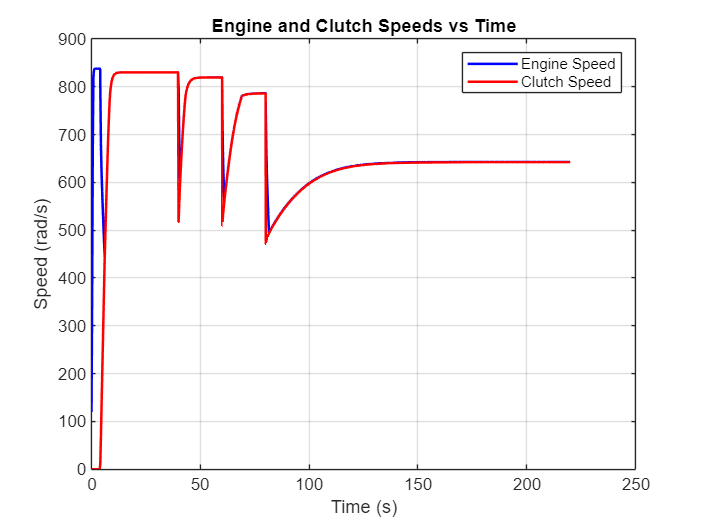

%% Plot results
figure;
plot(time, engine_speed, 'b', 'LineWidth', 1.5); hold on;
plot(time, clutch_speed, 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Speed (rad/s)');
title('Engine and Clutch Speeds vs Time');
legend('Engine Speed', 'Clutch Speed');
grid on;

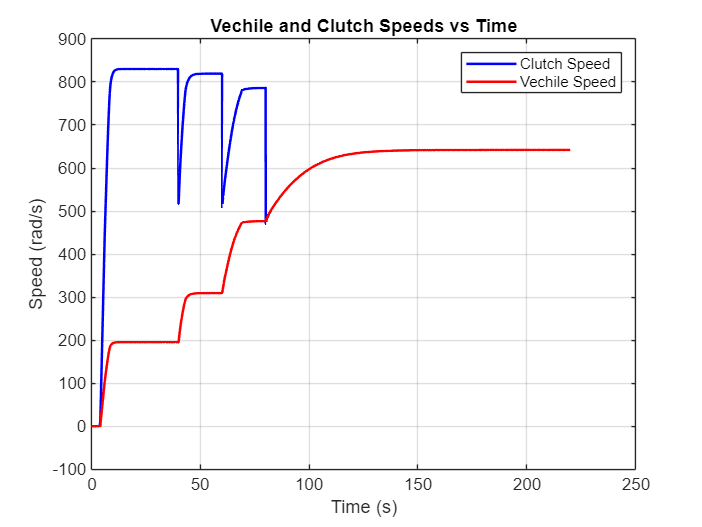

figure;
plot(time, clutch_speed, 'b', 'LineWidth', 1.5); hold on;
plot(time, vechil_speed, 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Speed (rad/s)');
title('Vechile and Clutch Speeds vs Time');
legend('Clutch Speed', 'Vechile Speed');
grid on;

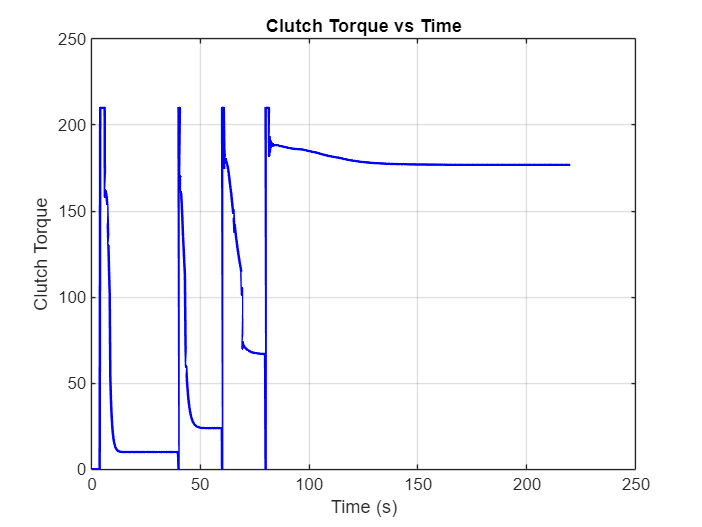

figure;
plot(time, clutch_torqu, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Clutch Torque');
title('Clutch Torque vs Time');
grid on;

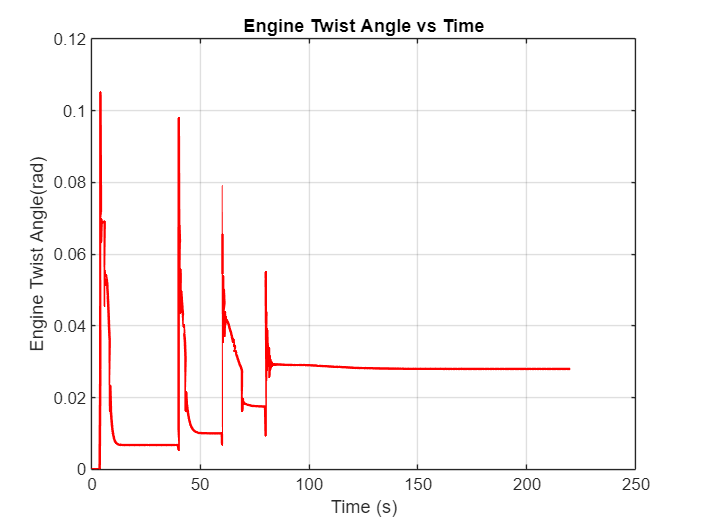

figure;
plot(time, twist_angle, 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Engine Twist Angle(rad)');
title('Engine Twist Angle vs Time');
grid on;

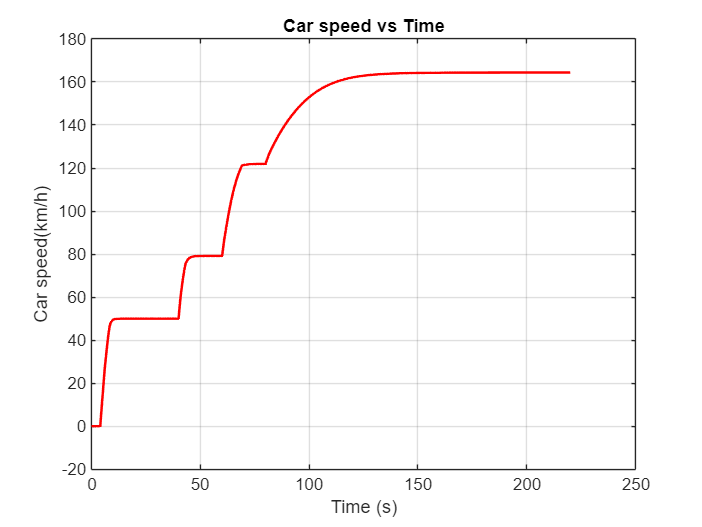

figure;
plot(time, vechil_speed*3.6*rw/id, 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Car speed(km/h)');
title('Car speed vs Time');
grid on;